# Perform Calculations by Group in Table

You can perform calculations on groups of data within table variables. In such calculations, you split one or more table variables into groups of data, perform a calculation on each group, and combine the results into one or more output variables. MATLAB® provides several functions that split data into groups and combine the results for you. You need only specify which table variables contain data, which variables define groups, and the function to apply to the groups of data.

For example, this diagram shows a simple grouped calculation that splits a numeric table variable into two groups of data, calculates the mean of each group, and then combines the mean values into an output variable.

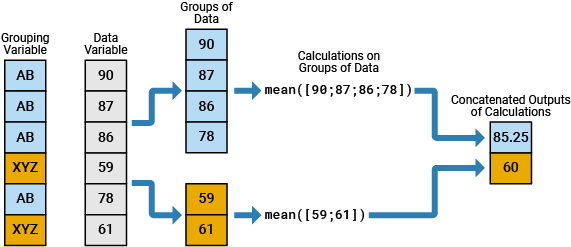

You can perform grouped calculations on table variables by using any of methods in this list:

- `groupsummary`, `groupcounts`, `groupfilter`, and `grouptransform`

- `varfun` and `rowfun`

- `findgroups` and `splitapply`

- [Compute by Group](docid:matlab_ref#mw_354e4ac3-6271-47e6-a886-135a6305ae62) task in the Live Editor

In most cases, `groupsummary` is the recommended function for grouped calculations. It is simple to use and returns a table with labels that describe results. The other listed functions, however, also offer capabilities that can be useful in some situations.

This topic has examples that use each of these functions. It ends with a summary of their behaviors and recommended usages.

## Create Table from File

The sample spreadsheet `outages.csv` contains data values that represent electric utility power outages in the United States. To create a table from the file, use the `readtable` function. To read text data from the file into table variables that are string arrays, specify the `TextType` name-value argument as `"string"`.

outages = readtable("outages.csv","TextType","string")

## Create `categorical` Grouping Variables

Table variables can have any data type. But conceptually, you can also think of tables as having two general kinds of variables: *data variables* and *grouping variables*.

- Data variables enable you to describe individual events or observations. For example, in `outages` you can think of the `OutageTime`, `Loss`, `Customers`, and `RestorationTime` variables as data variables.

- Grouping variables enable you to group together events or observations that have something in common. For example, in `outages` you can think of the `Region` and `Cause` variables as grouping variables. You can group together and analyze the power outages that occur in the same region or share the same cause.

Often, grouping variables contain a discrete set of fixed values that specify *categories*. The categories specify groups that data values can belong to. The `categorical` data type can be a convenient type for working with categories.

To convert `Region` and `Cause` to `categorical` variables, use the `convertvars` function.

outages = convertvars(outages,["Region","Cause"],"categorical")

## Calculate Statistics by Group in Table

You can calculate statistics by group in a table using functions such as `groupsummary`, `varfun`, and `splitapply`. These functions enable you to specify groups of data within a table and methods that perform calculations on each group. You can store the results in another table or in output arrays.

For example, determine the mean power loss and customers affected due to the outages in each region in the `outages` table. The recommended way to perform this calculation is to use the `groupsummary` function. Specify `Region` as the grouping variable, `mean` as the method to apply to each group, and `Loss` and `Customers` as the data variables. The output lists the regions (in the `Region` variable), the number of power outages per region (in the `GroupCount` variable), and the mean power loss and customers affected in each region (in the `mean_Loss` and `mean_Customers` variables, respectively).

meanLossByRegion = groupsummary(outages,"Region","mean",["Loss","Customers"])

The `groupsummary` function is recommended for several reasons:

- You can specify many common methods (such as `max`, `min`, and `mean`) by name, without using function handles.

- You can specify multiple methods in one call.

- `NaN`s, `NaT`s, and other missing values in the data variables are automatically *omitted* when calculating results.

The third point explains why the `mean_Loss` and `mean_Customers` variables do not have `NaN`s in the `meanLossByRegion` output table.

To specify multiple methods in one call to `groupsummary`, list them in an array. For example, calculate the maximum, mean, and minimum power loss by region.

lossStatsByRegion = groupsummary(outages,"Region",["max","mean","min"],"Loss")

The minimum loss in every region is zero. To analyze only those outages that resulted in losses greater than zero, exclude the rows in `outages` where the loss is zero. First create a vector of logical indices whose values are logical `1` (`true`) for rows where `outages.Loss` is greater than zero. Then index into `outages` to return a table that includes only those rows. Again, calculate the maximum, mean, and minimum power loss by region.

nonZeroLossIndices = outages.Loss > 0;
nonZeroLossOutages = outages(nonZeroLossIndices,:);
nonZeroLossStats = groupsummary(nonZeroLossOutages,"Region",["max","mean","min"],"Loss")

## Use Alternative Functions for Grouped Calculations

There are alternative functions that perform grouped calculations in tables. While `groupsummary` is recommended, the alternative functions are also useful in some situations.

- The `varfun` function performs calculations on variables. It is similar to `groupsummary`, but `varfun` can perform both grouped and ungrouped calculations.

- The `rowfun` function performs calculations along rows. You can specify methods that take multiple inputs or that return multiple outputs.

- The `findgroups` and `splitapply` functions can perform calculations on variables or along rows. You can specify methods that take multiple inputs or that return multiple outputs. The outputs of `splitapply` are arrays, not tables.

### Call `varfun` on Variables

For example, calculate the maximum power loss by region using `varfun`. The output table has a similar format to the output of `groupsummary`.

maxLossByVarfun = varfun(@max, ...
                         outages, ...
                         "InputVariables","Loss", ...
                         "GroupingVariables","Region")

However, there are significant differences when you use `varfun`:

- You must always specify the method by using a function handle.

- You can specify only one method.

- You can perform grouped *or* ungrouped calculations.

- `NaN`s, `NaT`s, and other missing values in the data variables are automatically *included* when calculating results.

The last point is a significant difference in behavior between `groupsummary` and `varfun`. For example, the `Loss` variable has `NaN`s. If you use `varfun` to calculate the mean losses, then by default the results are `NaN`s, unlike the default `groupsummary` results.

meanLossByVarfun = varfun(@mean, ...
                          outages, ...
                          "InputVariables","Loss", ...
                          "GroupingVariables","Region")

To omit missing values when using `varfun`, wrap the method in an anonymous function so that you can specify the `"omitnan"` option.

omitnanMean = @(x)(mean(x,"omitnan"));

meanLossOmitNaNs = varfun(omitnanMean, ...
                          outages, ...
                          "InputVariables","Loss", ...
                          "GroupingVariables","Region")

Another point refers to a different but related use case, which is to perform ungrouped calculations on table variables. To apply a method to all table variables without grouping, use `varfun`. For example, calculate the maximum power loss and the maximum number of customers affected in the entire table.

maxValuesInOutages = varfun(@max, ...
                            outages, ...
                            "InputVariables",["Loss","Customers"])

### Call `rowfun` on Rows

The `rowfun` function applies a method along the rows of a table. Where `varfun` applies a method to each specified variable, one by one, `rowfun` takes all specified table variables as input arguments to the method and applies the method once.

For example, calculate the median loss per customer in each region. To perform this calculation, first specify a function that takes two input arguments (`loss` and `customers`), divides the loss by the number of customers, and then returns the median.

medianLossCustFcn = @(loss,customers)(median(loss ./ customers,"omitnan"));

Then call `rowfun`. You can specify a meaningful output variable name by using the `OutputVariablesNames` name-value argument.

meanLossPerCustomer = rowfun(medianLossCustFcn, ...
                             outages, ...
                             "InputVariables",["Loss","Customers"], ...
                             "GroupingVariables","Region", ...
                             "OutputVariableNames","MedianLossPerCustomer")

You can also use `rowfun` when the method returns multiple outputs. For example, use `bounds` to calculate the minimum and maximum loss per region in one call to `rowfun`. The `bounds` function returns two output arguments.

boundsLossPerRegion = rowfun(@bounds, ...
                             outages, ...
                             "InputVariables","Loss", ...
                             "GroupingVariables","Region", ...
                             "OutputVariableNames",["MinLoss","MaxLoss"])

### Call `findgroups` and `splitapply` on Variables or Rows

You can use the `findgroups` function to define groups and then use `splitapply` to apply a method to each group. The `findgroups` function returns a vector of group numbers that identifies which group a row of data is part of. The `splitapply` function returns a numeric array of the outputs of the method applied to the groups.

For example, calculate the maximum power loss by region using `findgroups` and `splitapply`.

G = findgroups(outages.Region)
maxLossArray = splitapply(@max,outages.Loss,G)

Like `rowfun`, `splitapply` enables you to specify methods that return multiple outputs. Calculate both minima and maxima by using `bounds`.

[minLossArray,maxLossArray] = splitapply(@bounds,outages.Loss,G)

You can also specify methods that take multiple inputs. For example, use the `medianLossCustFcn` function again to calculate the median loss per customer. But this time, return the median loss per customer in each region as an array.

medianLossCustFcn = @(loss,customers)(median(loss ./ customers,"omitnan"));

medianLossArray = splitapply(medianLossCustFcn,outages.Loss,outages.Customers,G)

The numeric outputs of `findgroups` and `splitapply` are not annotated like the output of `groupsummary`. However, returning numeric outputs can have other benefits:

- You can use the output of `findgroups` in multiple calls to `splitapply`. You might want to use `findgroups` and `splitapply` for efficiency when you make many grouped calculations on a large table.

- You can create a results table with a different format by building it from the outputs of `findgroups` and `splitapply`.

- You can call methods that return multiple outputs.

- You can append the outputs of `splitapply` to an existing table.

## Append New Calculation to Existing Table

If you already have a table of results, you can append the results of another calculation to that table. For example, calculate the mean duration of power outages in each region in hours. Append the mean durations as a new variable to the `lossStatsByRegion` table.

First subtract the outage times from the restoration times to return the durations of the power outages. Convert these durations to hours by using the `hours` function.

D = outages.RestorationTime - outages.OutageTime;
H = hours(D)

Next use `mean` to calculate the mean durations. The outage durations have some `NaN` values because the outage and restoration times have some missing values. As before, wrap the method in an anonymous function to specify the `"omitnan"` option.

omitnanMean = @(x)(mean(x,"omitnan"));

Calculate the mean duration of power outages by region. Append it to `lossStatsByRegion` as a new table variable.

G = findgroups(outages.Region);
lossStatsByRegion.mean_Outage = splitapply(omitnanMean,H,G)

## Specify Groups as Bins

There is another way to specify groups. Instead of specifying categories as unique values in a grouping variable, you can bin values in a variable where values are distributed continuously. Then you can use those bins to specify groups.

For example, bin the power outages by year. To count the number of power outages per year, use the `groupcounts` function.

outagesByYear = groupcounts(outages,"OutageTime","year")

Visualize the number of outages per year. The number per year increases over time in this data set.

bar(outagesByYear.year_OutageTime,outagesByYear.GroupCount)

You can use `groupsummary` with bins as groups. For example, calculate the median values for customers affected and power losses by year.

medianLossesByYear = groupsummary(outages,"OutageTime","year","median",["Customers","Loss"])

Visualize the median number of customers affected by outages per year. Although the number of outages increased over time, the median number of affected customers decreased.

plot(medianLossesByYear,"year_OutageTime","median_Customers")

Return the rows of `outages` for years with more than 75 outages. To index into `outages` by those years, use the `groupfilter` function. To find the bins with more than 75 rows, specify an anonymous function that returns a logical `1` if the number of rows in a bin is greater than 75.

outages75 = groupfilter(outages,"OutageTime","year",@(x) numel(x) > 75)

## Summary of Behavior and Recommendations

Use these tips and recommendations to decide which functions to use to perform group calculations.

- Specify groups using either grouping variables or bins created from numeric, `datetime`, or `duration` variables.

- To perform calculations by group on data in tables or timetables, use the recommended function `groupsummary`. The related functions `groupcounts`, `groupfilter`, and `grouptransform` also are useful.

- Consider using `varfun` to automatically include missing values (such as `NaN`s and `NaT`s) when applying methods to groups of data. Also, `varfun` can perform both grouped and ungrouped calculations.

- Consider using `findgroups` and `splitapply` for efficiency when you make many consecutive grouped calculations on a large table.

- Consider using `findgroups` and `splitapply` to append new arrays to an existing table of results.

- To perform calculations using a method that returns multiple outputs, such as `bounds`, use either `rowfun` or `splitapply`.

- To perform calculations along rows using a method that requires multiple input arguments, use either `rowfun` or `splitapply`.

*Copyright 2024 The MathWorks, Inc.*